clear;

tic
for x = 0 : 500 %Graet_0 ~ Great_x
    disp(x);
    for w = 8 : 11
        for w_1 = 0 : 9
            a = ['Bold' num2str(x) '_' num2str(w) '_' num2str(w_1)]; %Bold_Signal
            a_1 = ['D:\Qt_projects\data6\Great\Great_' num2str(x) '\Bold' num2str(w) '.' num2str(w_1) '00000.dat'];
            b = ['cm' num2str(x) '_' num2str(w) '_' num2str(w_1)]; %Correlation_Matrix
            
            %importdata
            if exist(a_1, 'fiLe') == 2
                d = importdata(a_1);
                eval([a '=d']);
                f = eval(a);
                
                %correlation
                g = zeros(length(f(:, 1)),length(f(:, 1)));
                for i = 1 : length(f(:, 1))
                    for z = 1 : length(f(:, 1))
                        h = corrcoef(f(i, :),f(z, :));
                        g(i,z) = h(1, 2);
                    end
                end
                g = abs(g);
                g(g >= 0.99) = 0;
                eval([b '=g']);
            end
            clc;
        end
    end
end
toc

tic
save('Great_500.mat');
toc

clear;
tic
load('Great_500.mat');
toc

load('dti_2018_12_15.txt');
dti = dti_2018_12_15;

load('dti.txt');
dti_temp = dti;
% dti_temp(dti_temp >= 1) = 1;
dti_r = reshape(dti_temp, [1, 8100]);

clear c_dti h_dti;

tic
for x = 0 : 500 %Graet_0 ~ Great_x
    disp(x);
    k = 1;
    for w = 8 : 11
        for w_1 = 0 : 9
            b = ['cm' num2str(x) '_' num2str(w) '_' num2str(w_1)]; %Correlation_Matrix
            
            if exist(b, 'var') == 1
                z = 1;
                g = eval(b);
                for td = 0.091 : 0.001 : 0.11
                    %                     [Ge, Le, Lp, Cp, Ec, Kp, sigma] = netpropv2(g, td);
                    %                     Data{z, k, x + 1} = [Ge, Le, Lp, Cp, Ec, Kp, sigma];
                    
                    cij = g;
                    cij(cij <= td) = 0;
                    cij(cij > td) = 1;
                    
                    m = abs(corrcoef(cij, dti_temp));
                    c_dti(z, k, x + 1) = m(1, 2);
                    
                    
                    cij_r = reshape(cij, [1, 8100]);
                    hm = pdist2(cij_r, dti_r, 'hamming');
                    %                     hm = mean(diag(hm_m));
                    %                     hm = sum(sum((cij - dti_temp).^2)) / 8100;
                    h_dti(z, k, x + 1) = hm;
                    
                    Td(z) = td;
                    z = z + 1;
                end
                %cm_all{x + 1, k} = g;
            end
            k = k + 1;
        end
    end
end
toc


if exist('Data', 'var') == 1
    [m, n, o] = size(Data);
    Ge_ij_all = zeros(m, n, o);
    Le_ij_all = zeros(m, n, o);
    Lp_ij_all = zeros(m, n, o);
    Cp_ij_all = zeros(m, n, o);
    Ec_ij_all = zeros(m, n, o);
    Kp_ij_all = zeros(m, n, o);
    
    Ge_ij = zeros(m, n);
    Le_ij = zeros(m, n);
    Lp_ij = zeros(m, n);
    Cp_ij = zeros(m, n);
    Ec_ij = zeros(m, n);
    Kp_ij = zeros(m, n);
    
    for k = 1 : o
        for i = 1 : m
            for j = 1 : n
                Ge_ij_all(i, j, k) = Data{i, j, k}(1, 1);
                Le_ij_all(i, j, k) = Data{i, j, k}(1, 2);
                Lp_ij_all(i, j, k) = Data{i, j, k}(1, 3);
                Cp_ij_all(i, j, k) = Data{i, j, k}(1, 4);
                Ec_ij_all(i, j, k) = Data{i, j, k}(1, 5);
                Kp_ij_all(i, j, k) = Data{i, j, k}(1, 6);
            end
        end
    end
    
    Ge_ij_all(isnan(Ge_ij_all)) = 0;
    Le_ij_all(isnan(Le_ij_all)) = 0;
    Lp_ij_all(isinf(Lp_ij_all)) = 2.5;
    Cp_ij_all(isnan(Cp_ij_all)) = 0;
    Ec_ij_all(isnan(Ec_ij_all)) = 0;
    Kp_ij_all(isnan(Kp_ij_all)) = 0;
    
    for k = 1 : o
        Ge_ij = Ge_ij +  Ge_ij_all(:, :, k);
        Le_ij = Le_ij +  Le_ij_all(:, :, k);
        Lp_ij = Lp_ij +  Lp_ij_all(:, :, k);
        Cp_ij = Cp_ij +  Cp_ij_all(:, :, k);
        Ec_ij = Ec_ij +  Ec_ij_all(:, :, k);
        Kp_ij = Kp_ij +  Kp_ij_all(:, :, k);
    end
    
    Ge_ij = Ge_ij ./ (x + 1);
    Le_ij = Le_ij ./ (x + 1);
    Lp_ij = Lp_ij ./ (x + 1);
    Cp_ij = Cp_ij ./ (x + 1);
    Ec_ij = Ec_ij ./ (x + 1);
    Kp_ij = Kp_ij ./ (x + 1);
    
    cdti_mean = zeros(m, n);
    hdti_mean = zeros(m, n);
    for i = 1 : x + 1
        cdti_mean = cdti_mean + c_dti(:, :, i);
        hdti_mean = hdti_mean + h_dti(:, :, i);
    end
    cdti_mean = cdti_mean ./ (x + 1);
    hdti_mean = hdti_mean ./ (x + 1);
end

tic
save('Great_500.mat');
toc

    cdti_mean = zeros(20, 31);
    hdti_mean = zeros(20, 31);
    for i = 1 : x + 1
        cdti_mean = cdti_mean + c_dti(:, :, i);
        hdti_mean = hdti_mean + h_dti(:, :, i);
    end
    cdti_mean = cdti_mean ./ (x + 1);
    hdti_mean = hdti_mean ./ (x + 1);

subplot(1, 2, 1), mesh(1 : n, Td, cdti_mean);
xlabel('E/I', 'FontName', 'Arial');
ylabel('T_d', 'FontName', 'Arial');
zlabel('Correlation', 'FontName', 'Arial');
set(gca, 'YDir', 'reverse');
set(gca, 'Xtick', [1, 16, 31]);
set(gca, 'XTickLabel', {'8.0', '9.5', '11.0'});

subplot(1, 2, 2), mesh(1 : n, Td, hdti_mean);
xlabel('E/I', 'FontName', 'Arial');
ylabel('T_d', 'FontName', 'Arial');
zlabel('Hamming', 'FontName', 'Arial');
set(gca, 'YDir', 'reverse');
set(gca, 'Xtick', [1, 16, 31]);
set(gca, 'XTickLabel', {'8.0', '9.5', '11.0'});

subplot(3, 2, 1),mesh(1 : n, Td, Ge_ij);
xlabel('E/I', 'FontName', 'Arial');
ylabel('T_d', 'FontName', 'Arial');
zlabel('E_{global}', 'FontName', 'Arial');
set(gca, 'YDir', 'reverse');
set(gca, 'Xtick', [1, 16, 31]);
set(gca, 'XTickLabel', {'8.0', '9.5', '11.0'});
subplot(3, 2, 2),mesh(1 : n, Td, Le_ij);
xlabel('E/I', 'FontName', 'Arial');
ylabel('T_d', 'FontName', 'Arial');
zlabel('E_{local}', 'FontName', 'Arial');
set(gca, 'YDir', 'reverse');
set(gca, 'Xtick', [1, 16, 31]);
set(gca, 'XTickLabel', {'8.0', '9.5', '11.0'});
subplot(3, 2, 3),mesh(1 : n, Td, Lp_ij);
xlabel('E/I', 'FontName', 'Arial');
ylabel('T_d', 'FontName', 'Arial');
zlabel('L', 'FontName', 'Arial');
set(gca, 'Xtick', [1, 16, 31]);
set(gca, 'XTickLabel', {'8.0', '9.5', '11.0'});
subplot(3, 2, 4),mesh(1 : n, Td, Cp_ij);
xlabel('E/I', 'FontName', 'Arial');
ylabel('T_d', 'FontName', 'Arial');
zlabel('C_{global}', 'FontName', 'Arial');
set(gca, 'YDir', 'reverse');
set(gca, 'Xtick', [1, 16, 31]);
set(gca, 'XTickLabel', {'8.0', '9.5', '11.0'});
subplot(3, 2, 5),mesh(1 : n, Td, Ec_ij);
xlabel('E/I', 'FontName', 'Arial');
ylabel('T_d', 'FontName', 'Arial');
zlabel('E_{corr}', 'FontName', 'Arial');
set(gca, 'Xtick', [1, 16, 31]);
set(gca, 'XTickLabel', {'8.0', '9.5', '11.0'});
subplot(3, 2, 6),mesh(1 : n, Td, Kp_ij);
xlabel('E/I', 'FontName', 'Arial');
ylabel('T_d', 'FontName', 'Arial');
zlabel('S', 'FontName', 'Arial');
set(gca, 'YDir', 'reverse');
set(gca, 'Xtick', [1, 16, 31]);
set(gca, 'XTickLabel', {'8.0', '9.5', '11.0'});

clear;
tic
load('Great_500.mat');
toc

clear cm_all;
tic
for x = 0 : 50 %Graet_0 ~ Great_x
    disp(x);
    k = 1;
    for w = 8 : 11
        for w_1 = 0 : 9
            b = ['cm' num2str(x) '_' num2str(w) '_' num2str(w_1)]; %Correlation_Matrix
            
            if exist(b, 'var') == 1
                g = eval(b);
                cm_all{x + 1, k} = g;
            end
            
            k = k + 1;
        end
    end
end

     0

     1

     2

     3

     4

     5

     6

     7

     8

     9

    10

    11

    12

    13

    14

    15

    16

    17

    18

    19

    20

    21

    22

    23

    24

    25

    26

    27

    28

    29

    30

    31

    32

    33

    34

    35

    36

    37

    38

    39

    40

    41

    42

    43

    44

    45

    46

    47

    48

    49

    50



toc

时间已过 0.217771 秒。


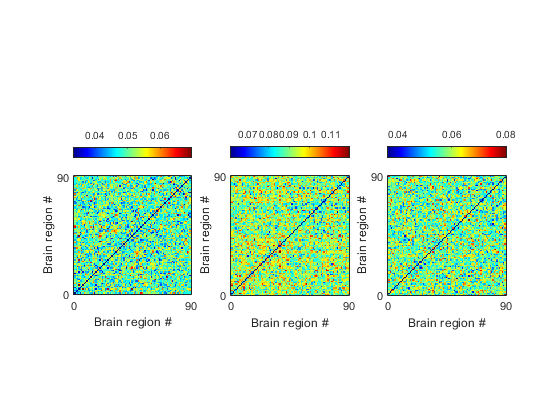

cm8_0_mean = zeros(90, 90);
cm9_5_mean = zeros(90, 90);
cm11_0_mean = zeros(90, 90);

%x = 500;
for i = 1 : x + 1
    cm8_0_mean = cm8_0_mean + cm_all{i, 1};
    cm9_5_mean = cm9_5_mean + cm_all{i, 16};
    cm11_0_mean = cm11_0_mean + cm_all{i, 31};
end

cm8_0_mean = cm8_0_mean ./ (x + 1);
cm9_5_mean = cm9_5_mean ./ (x + 1);
cm11_0_mean = cm11_0_mean ./ (x + 1);

for i = 1 : 90
    cm8_0_mean(i, i) = NaN;
    cm9_5_mean(i, i) = NaN;
    cm11_0_mean(i, i) = NaN;
end


%temp = [0.044 0.0997];

subplot(1, 3, 1), imagesc(cm11_0_mean);
colorbar northoutside;
set(gca,'YDir','normal');
xlabel('Brain region #', 'FontName', 'Arial');
ylabel('Brain region #', 'FontName', 'Arial');
set(gca,'DataAspectRatio',[1 1 1]);
set(gca, 'Xtick', [1, 90]);
set(gca, 'XTickLabel', {'0', '90'});
set(gca, 'Ytick', [1, 90]);
set(gca, 'YTickLabel', {'0', '90'});

%caxis(temp);

subplot(1, 3, 2), imagesc(cm9_5_mean);
set(gca,'YDir','normal');
colorbar northoutside;
xlabel('Brain region #', 'FontName', 'Arial');
ylabel('Brain region #', 'FontName', 'Arial')
set(gca,'DataAspectRatio',[1 1 1]);
set(gca, 'Xtick', [1, 90]);
set(gca, 'XTickLabel', {'0', '90'});
set(gca, 'Ytick', [1, 90]);
set(gca, 'YTickLabel', {'0', '90'});

%caxis(temp);

subplot(1, 3, 3), imagesc(cm8_0_mean);
set(gca,'YDir','normal');
colorbar northoutside;
xlabel('Brain region #', 'FontName', 'Arial');
ylabel('Brain region #', 'FontName', 'Arial');
set(gca,'DataAspectRatio',[1 1 1]);
set(gca, 'Xtick', [1, 90]);
set(gca, 'XTickLabel', {'0', '90'});
set(gca, 'Ytick', [1, 90]);
set(gca, 'YTickLabel', {'0', '90'});

%caxis(temp);

colormap jet;